ds_rate={'ori','ds2','ds5','ds10','ds20','ds50','ds100'}

ds_rate = 1×7 cell 배열
    {'ori'}    {'ds2'}    {'ds5'}    {'ds10'}    {'ds20'}    {'ds50'}    {'ds100'}


s=1

s = 1

e=3000

e = 3000

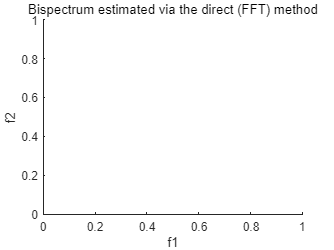

for i=1:length(ds_rate)
    expression=strcat("rpm=cyl_06_45.",ds_rate{i},"_rpm;");
    
    avg=mean(rpm);
    IASFR=rpm/avg;
    IASFR_sample=IASFR(s:e);
    IMF=zeros(6,length(IASFR_sample));
    IMF=emd(IASFR_sample,"MaxNumIMF",6);
    tmp=rica(IMF,3);
    ica=transform(tmp,IMF);
    [Bspec,waxis]=BISPECD(ica,1024,20,3,0);
    reduce_start=(length(Bspec)/2)-(length(Bspec)/20);
    reduce_end=(length(Bspec)/2)+(length(Bspec)/20);
    r_bispec=Bspec(reduce_start:reduce_end,reduce_start:reduce_end);
    expression=strcat("B",num2str(i),"=abs(r_bispec);");
    eval(expression);

end

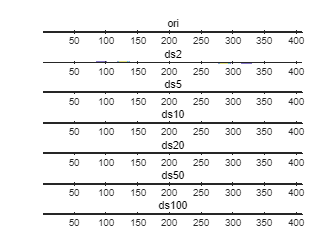

subplot(7,1,1)
contour(B1,3);
title('ori')
subplot(7,1,2)
contour(B2,3);
title('ds2')
subplot(7,1,3)
contour(B3,3);
title('ds5')
subplot(7,1,4)
contour(B4,3);
title('ds10')
subplot(7,1,5)
contour(B5,3);
title('ds20')
subplot(7,1,6)
contour(B6,3);
title('ds50')
subplot(7,1,7)
contour(B7,3)
title('ds100')